clc; clear;

## System parameters

m = 1;      % [kg]
k = 1.58e6; % [N/m]
eta = 0.05; % [-]

## 1 - Excitation

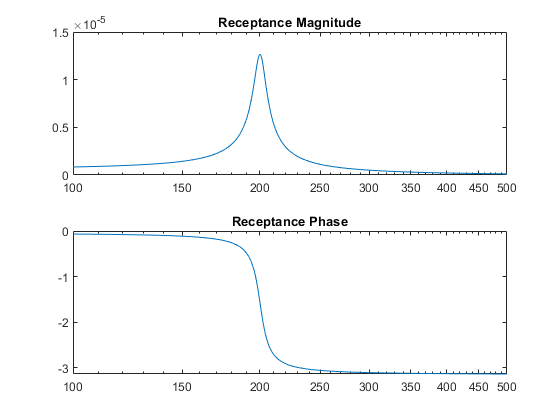

F = 1;              % [N], excitation amplitude
range_start = 100;  % [Hz]
range_finish = 500; % [Hz]
df = 0.5;           % [Hz], frequency increment
f = range_start:df:range_finish;
w = 2*pi*f;

receptance = @(w) 1./(k - w.^2*m + 1j*k*eta); % Histeretic damping

H = receptance(w);
%H = H.*(1 + 1e-2*randn(1,length(f)));

nfig = 1;
figure(nfig);
subplot(2,1,1)
    semilogx(f, abs(H));
    title("Receptance Magnitude");
    xlabel("");
    ylabel("");
subplot(2,1,2)
    semilogx(f, angle(H));
    title("Receptance Phase");
    xlabel("");
    ylabel("");

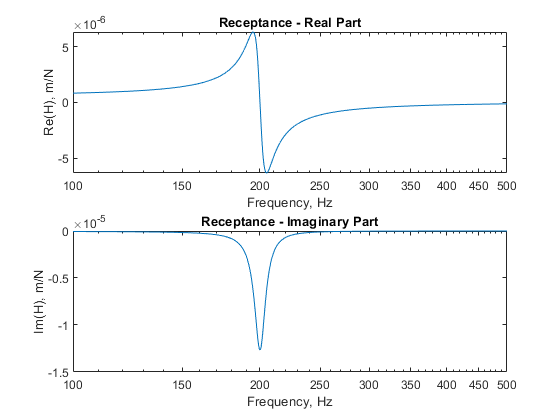


nfig = nfig + 1;
figure(nfig);
subplot(2,1,1)
    semilogx(f, real(H));
    title("Receptance - Real Part");
    xlabel("Frequency, Hz");
    ylabel("Re(H), m/N");
subplot(2,1,2)
    semilogx(f, imag(H));
    title("Receptance - Imaginary Part");
    xlabel("Frequency, Hz");
    ylabel("Im(H), m/N");

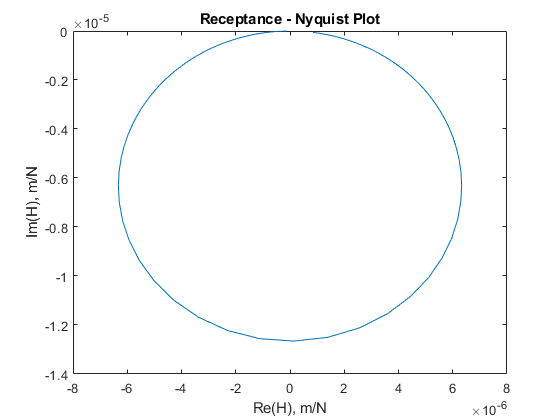

nfig = nfig + 1;
figure(nfig);
plot(real(H), imag(H));
title("Receptance - Nyquist Plot");
xlabel("Re(H), m/N");
ylabel("Im(H), m/N");

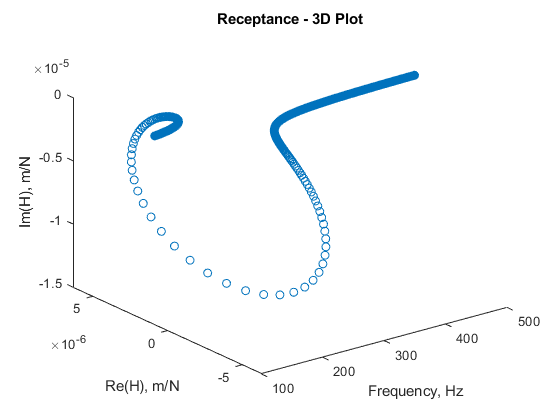

nfig = nfig + 1;
figure(nfig);
plot3(f, real(H), imag(H), "o");
title("Receptance - 3D Plot");
xlabel("Frequency, Hz");
ylabel("Re(H), m/N");
zlabel("Im(H), m/N");

## 1.1 Find the system's damping using the Halfpower Method

[receptance_pk,central_frq] = findpeaks(abs(H),f, 'MinPeakHeight',0.1e-5,...
                                                  'MinPeakDistance',200);
drop = receptance_pk*10^(-3/20);    % 3dB drop in signal strength
%drop = receptance_pk/sqrt(2);      % half-power definition

FRQ = @(frf) interp1(abs(H),f,frf,"spline"); % interpolates and returns the frequency
bandwidth = 2*abs(central_frq - FRQ(drop))

bandwidth = 10.9148

central_frq

central_frq = 200

eta_estimated = bandwidth/central_frq

eta_estimated = 0.0546

## 1.2 Find the bandwidth of the Halfpower Method using only the real part

[pk1,f_a] = findpeaks(real(H),f, 'MinPeakHeight',2e-6,...
                                 'MinPeakDistance',200);  
[pk2,f_b] = findpeaks(-real(H),f,'MinPeakHeight',2e-6,...
                                 'MinPeakDistance',200); %#ok<*ASGLU> 
central_frq2 = (f_a + f_b)/2;
bandwidth2 = abs(f_b - f_a)

bandwidth2 = 10

central_frq2

central_frq2 = 200

eta_estimated2 = abs(f_b-f_a)/central_frq2

eta_estimated2 = 0.0500

## 1.3 Find the half power point using the Nyquist diagram

[pk1,f_a] = findpeaks(real(H),f, 'MinPeakHeight',2e-6,...
                                 'MinPeakDistance',200);
[pk2,f_b] = findpeaks(-real(H),f, 'MinPeakHeight',2e-6,...
                                 'MinPeakDistance',200);
[pk3,central_frq3] = findpeaks(-imag(H),f, 'MinPeakHeight',2e-6,...
                                           'MinPeakDistance',200);
                                      
bandwidth3 = abs(f_b-f_a)

bandwidth3 = 10

eta_estimated3 = bandwidth3/central_frq3

eta_estimated3 = 0.0500

## 1.4 Find the system's damping using the Imaginary part of the Receptance

[img_peak_at_ressonance,central_frq3] = findpeaks(-imag(H),f, 'MinPeakHeight',2e-6,...
                                                              'MinPeakDistance',200);
eta_estimated4 = -1/(k*-img_peak_at_ressonance)

eta_estimated4 = 0.0500

## 1.5 Find the dissipated energy in each cycle at ressonance

FRF = @(frq) interp1(f,H,frq,"spline"); % Interpolate the FRF to any frequency
displacement_at_ressonance = abs(FRF(central_frq3))*F; % [m]
E_vib = pi*m*(central_frq3*2*pi)^2*displacement_at_ressonance^2

E_vib = 7.9481e-04

phi2 = angle(FRF(central_frq3));
E_diss = abs(pi*F*displacement_at_ressonance*sin(phi))

E_diss = 3.9762e-05

eta_estimated5 = E_diss/E_vib

eta_estimated5 = 0.0500

## 1.6 Modal Stiffness

modal_stiffness = abs(1/(receptance(2*pi*10))) % inverse of the receptance at f=10Hz

modal_stiffness = 1.5780e+06

## 1.6 Inertance and modal mass

modal_mass = 1/abs(receptance(2*pi*2000)*(2*pi*2000)^2) 

modal_mass = 0.9900

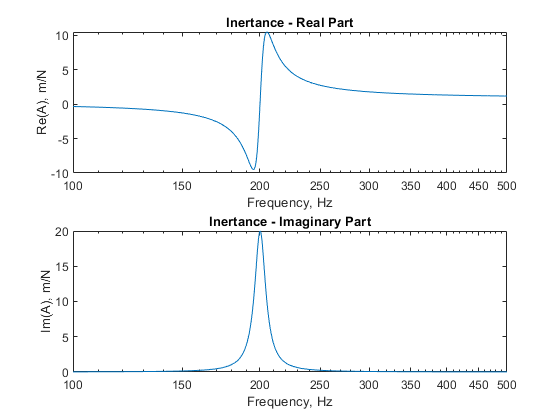


nfig = nfig + 1;
figure(nfig);
subplot(2,1,1)
    semilogx(f, real(-(w.^2).*H));
    title("Inertance - Real Part");
    xlabel("Frequency, Hz");
    ylabel("Re(A), m/N");
subplot(2,1,2)
    semilogx(f, imag(-(w.^2).*H));
    title("Inertance - Imaginary Part");
    xlabel("Frequency, Hz");
    ylabel("Im(A), m/N");

## 2 Viscous Model

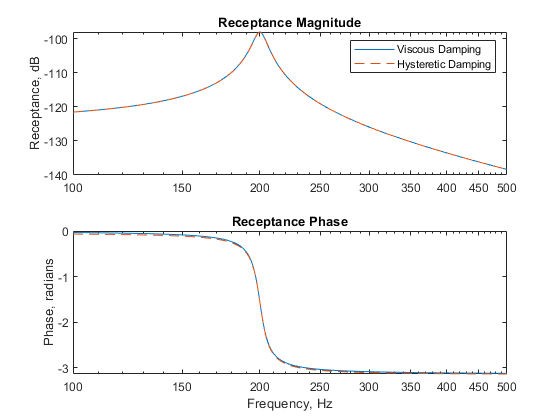

c = 62.83; % kg/s visocus damping parameter
receptance2 = @(w) 1./(k - w.^2*m + 1j*w*c); % Viscous damping SDOF

H2 = receptance2(w);
%H2 = H2.*(1 + 1e-2*randn(1,length(f)));

nfig = nfig+1;
figure(nfig);
subplot(2,1,1)
    semilogx(f, 20*log10(abs(H2))); hold on;
    semilogx(f, 20*log10(abs(H)), "--"); hold off;
    title("Receptance Magnitude");
    legend("Viscous Damping", "Hysteretic Damping")
    xlabel("");
    ylabel("Receptance, dB");
subplot(2,1,2)
    semilogx(f, angle(H2)); hold on;
    semilogx(f, angle(H), "--"); hold off;
    title("Receptance Phase");
    xlabel("Frequency, Hz");
    ylabel("Phase, radians");

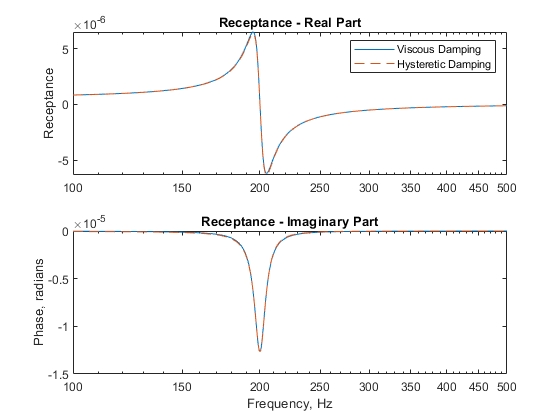

nfig = nfig+1;
figure(nfig);
subplot(2,1,1)
    semilogx(f, real(H2)); hold on;
    semilogx(f, real(H), "--"); hold off;
    title("Receptance - Real Part");
    legend("Viscous Damping", "Hysteretic Damping")
    xlabel("");
    ylabel("Receptance");
subplot(2,1,2)
    semilogx(f, imag(H2)); hold on;
    semilogx(f, imag(H), "--"); hold off;
    title("Receptance - Imaginary Part");
    xlabel("Frequency, Hz");
    ylabel("Phase, radians");

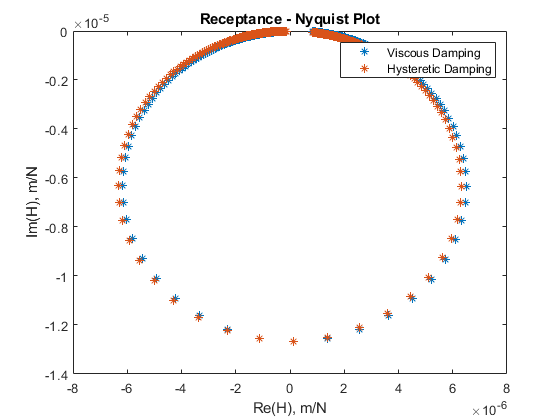

nfig = nfig + 1;
figure(nfig);
plot(real(H2), imag(H2),"*"); hold on;
plot(real(H), imag(H), "*"); hold off;
title("Receptance - Nyquist Plot");
xlabel("Re(H), m/N");
ylabel("Im(H), m/N");
legend("Viscous Damping", "Hysteretic Damping")

[img_peak_at_ressonance,res_frq_hyst] = findpeaks(-imag(H),f, 'MinPeakHeight',2e-6,...
                                                              'MinPeakDistance',200);
[img_peak_at_ressonance,res_frq_visc] = findpeaks(-imag(H2),f, 'MinPeakHeight',2e-6,...
                                                              'MinPeakDistance',200);
res_frq_hyst

res_frq_hyst = 200

res_frq_visc

res_frq_visc = 200

## 3 Inverse of Receptance

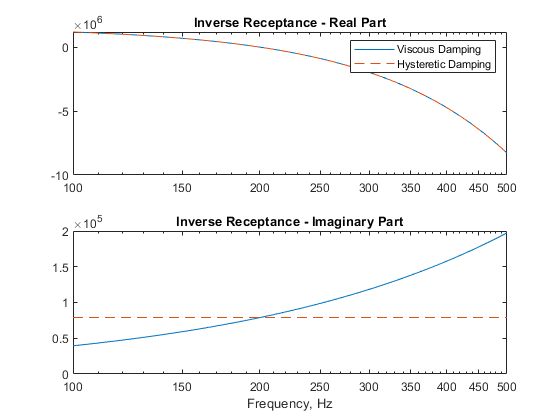

inverse = 1./H;
inverse2 = 1./H2;

nfig = nfig+1;
figure(nfig);
subplot(2,1,1)
    semilogx(f, real(inverse2)); hold on;
    semilogx(f, real(inverse), "--"); hold off;
    title("Inverse Receptance - Real Part");
    legend("Viscous Damping", "Hysteretic Damping")
    xlabel("");
    ylabel("");
subplot(2,1,2)
    semilogx(f, imag(inverse2)); hold on;
    semilogx(f, imag(inverse), "--"); hold off;
    title("Inverse Receptance - Imaginary Part");
    xlabel("Frequency, Hz");
    ylabel("");

eta_estimated6 = imag(inverse(100))/modal_stiffness

eta_estimated6 = 0.0501